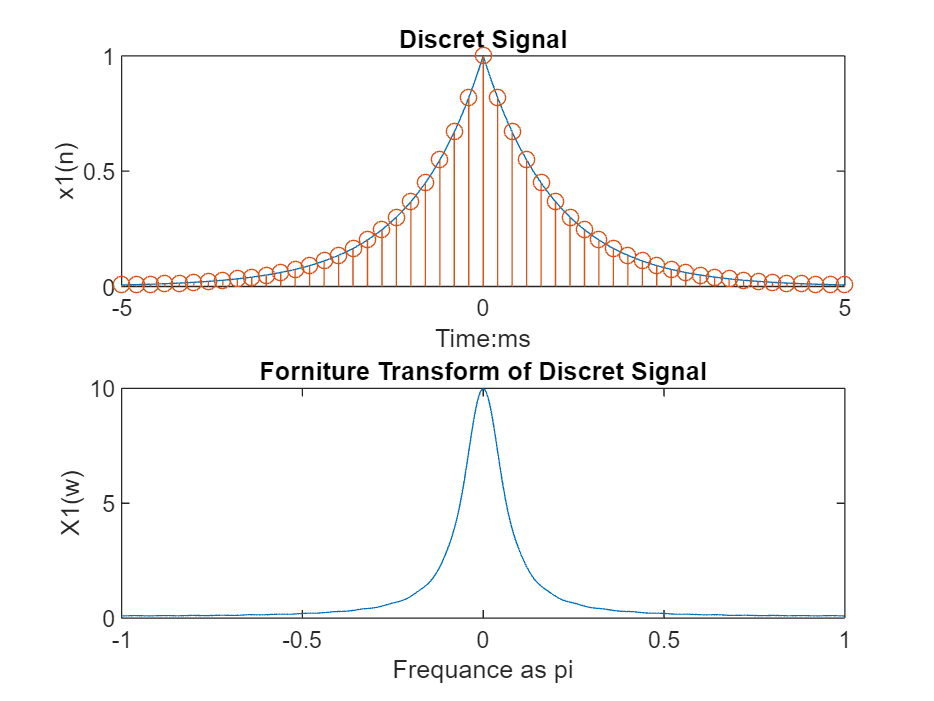

dt=0.00005;t=-0.005:dt:0.005;
xa=exp(-1000*abs(t));

fs=5000;Ts=1/fs;n=-25:1:25;
x=exp(-1000*abs(n*Ts));

N=500;k=0:1:N;w=pi*k/N;
X=x*exp(-j*n'*w);X=real(X);
w=[-fliplr(w),w(2:N+1)];X=[fliplr(X),X(2:N+1)];
subplot(2,1,1);plot(t*1000,xa),xlabel('Time:ms'),ylabel('x1(n)');
title('Discret Signal');hold on;
stem(n*Ts*1000,x),hold off;
subplot(2,1,2);plot(w/pi,X);xlabel('Frequance as pi');ylabel('X1(w)');
title('Forniture Transform of Discret Signal');